m1=-1;
m2=1;
P1=0.5;
P2=0.5;
N=1000;

var1=0.25;
var2=0.49;
var3=1.00;

x11=sqrt(var1)*randn(1,N)+m1;
x12=sqrt(var1)*randn(1,N)+m2;
x1=[x11 x12];

x21=sqrt(var2)*randn(1,N)+m1;
x22=sqrt(var2)*randn(1,N)+m2;
x2=[x21 x22];

x31=sqrt(var3)*randn(1,N)+m1;
x32=sqrt(var3)*randn(1,N)+m2;
x3=[x31 x32];

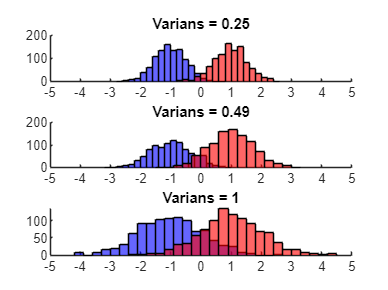

figure;
subplot(3,1,1);
hold on
histogram(x11,'FaceColor','b');
histogram(x12,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var1);

subplot(3,1,2);
hold on
histogram(x21,'FaceColor','b');
histogram(x22,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var2);

subplot(3,1,3);
hold on
histogram(x31,'FaceColor','b');
histogram(x32,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var3);

% Error rates
disp("P_e1: "+erfc(1/sqrt(var1)));

P_e1: 0.0046777


disp("P_e2: "+erfc(1/sqrt(var2)));

P_e2: 0.043352


disp("P_e3: "+erfc(1/sqrt(var3)));

P_e3: 0.1573
